### Computational Method in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Implicit Runge-Kutta Methods

#### Learning outcomes

On successful completion of this page readers will be able to:

- [Determine the order](http://localhost:8888/notebooks/IRK_methods.ipynb#Dermining-the-order-of-an-implicit-Runge-Kutta-method) of an implicit Runge-Kutta method;

- Derive Gauss-Legendre, Radau, DIRK and SDIRK implicit Runge-Kutta methods;

- Apply implicit Runge-Kutta methods to solve initial value problems.

**Implicit Runge-Kutta** (IRK) methods and **Explicit Runge-Kutta** (ERK) methods are the two main types of the family of Runge-Kutta methods. ERK methods are straightforward to apply to solve an ordinary differential equation but are not suitable for **stiff** systems. This is why we need to also consider IRK methods.

The general form of an IRK method to solve a first-order ODE $y'=f(t, y)$


$$y_{n+1} = y_n + h\sum_{i=1}^s b_ik_i, \\ 
\quad k_i = f(t_n + c_ih, y_n + h\sum_{j=1}^s a_{ij}k_j).$$


Here $y_n = y(t_n)$ is the solution at a discrete point in the domain $t_n$; $y_{n+1}=y(t_n+h)$ is the solution at some small step $h$ along the domain; $a_{ij}$, $b_i$ and $c_i$ are coefficients that define a particular method and $k_i$ are intermediate **stage values** used to calculate $y_{n+1}$.

It is common to represent the $a_{ij}$, $b_i$ and $c_i$ coefficients in a **Butcher tableau**


$$\begin{array}{c|cccc} 
c_1 & a_{11} & a_{12} & \cdots & a_{1s} \\ 
c_2 & a_{21} & a_{22} & \cdots & a_{2s} \\ 
\vdots & \vdots & \vdots & \ddots & \vdots \\ 
c_s & a_{s1} & a_{s2} & \cdots & a_{ss}  \\
 & b_1 & b_2 & \cdots & b_s \end{array}$$


*Note that Butcher tableaus are usually represented with partition lines separating the *$a_{ij}$*, *$b_i$* and *$c_i$* values (see *[examples](https://en.wikipedia.org/wiki/Runge%E2%80%93Kutta_methods#Explicit_Runge%E2%80%93Kutta_methods)*). MATLAB's LaTeX renderer does not permit this for some reason.*

The $A$ matrix of an IRK method has non-zero elements in the upper triangular region and on the main diagonal whereas the $A$ matrix for an ERK method only has non-zero elements in the lower triangular region.

## Determining the order of an implicit Runge-Kutta method

One of the differences between IRK and ERK methods is that an IRK method can achieve the same accuracy as an ERK method but using fewer stages. To determine the order of an IRK method we need to consider the **order conditions** that govern the values of $A$, $\mathbf{b}$ and $\mathbf{c}$ which are


$$\begin{array}{lrllll}
B(K): & \sum_{i=1}^s b_i c_i^{j-1} = &\frac{1}{j}, & j = 1, 2, \ldots, k, && (1) \\
C(k): & \sum_{j=1}^s a_{ij} c_j^{\ell-1} =& \frac{1}{\ell}c_i^\ell, & i = 1, 2, \ldots, s, & \ell = 1, 2, \ldots, k, & (2)\\
D(k)) : & \sum_{i=1}^s b_i c_i^{\ell-1}a_{ij} =& \frac{1}{\ell}b_j(1-c_j^\ell), & j=1, 2, \ldots, s, & \ell = 1, 2, \ldots, k. \qquad & (3)
\end{array}$$


If $G(k)$ represents the fact that a given IKR method has order $k$ then it can be shown that


$$B(k) \text{ and } C(\lfloor k/2 \rfloor) \text{ and } D(\lfloor k/2 \rfloor) \Longrightarrow G(k)$$


So to determine the order of an IRK method we need to find the highest value of $k$ for which equation (1) is satisfied and which equations (2) and (3) are satisfied for $\lfloor k/2\rfloor$ (i.e. the integer part of $k/2$).

#### Example 1

Determine the order of the following IRK method


$$\begin{array}{c|cc} \frac{1}{4} & \frac{1}{4} & 0 \\ \frac{3}{4} & \frac{1}{2} & \frac{1}{4} \\ & \frac{1}{2} & \frac{1}{2} \end{array}$$


Checking the $B(k)$ order condition:


$$\begin{array}{lrlrl}
j = 1: & LHS =&b_1c_1^0 + b_2c_2^0 = \frac{1}{2}(1) + \frac{1}{2}(1) = 1,  & RHS =& 1, \\
j = 2: & LHS =& b_1 c_1^1 + b_2c_2^1 = \frac{1}{2}\left(\frac{1}{4}\right) + \frac{1}{2}\left(\frac{3}{4}\right) = \frac{1}{2}, & RHS =& \frac{1}{2}, \\
j = 3: & LHS =& b_1c_1^2 + b_2c_2^2 = \frac{1}{2}\left(\frac{1}{4}\right)^2 + \frac{1}{2}\left(\frac{3}{4}\right)^2 = \frac{5}{16}, \qquad & RHS =& \frac{1}{3}.
\end{array}$$
 

So the $B(k)$ order condition is satisfied up to $k=j=2$. Now we need to check whether $C(k)$ order condition is satisfied up to $k=1$.


$$\begin{array}{llll}
\ell = 1, & i = 1, & LHS = a_{11} c_1^0 + a_{12}c_2^0 = \frac{1}{4}(1) + 0(1) = \frac{1}{4}, & RHS = \frac{1}{\ell}c_1^\ell = \frac{1}{4}, \\
\ell = 1, & i = 2, & LHS=a_{21}c_1^0 + a_{22}c_2^0 = \frac{1}{2}(1) + \frac{1}{4}(1) = \frac{3}{4}, & RHS = \frac{1}{\ell}c_2^{\ell}= \frac{3}{4}.

\end{array}$$


So the $C(k)$ order condition is satisfied up to $k=1$. Now we need to check whether the $D(k)$ order condition is satisfied up to $k=1$


$$\begin{array}{lll}
\ell = 1, & j = 1, & LHS = b_1c_1^0a_{11} + b_2c_2^0a_{21} = \frac{1}{2}(1)\left(\frac{1}{4}\right) + \frac{1}{2}(1)\left(\frac{1}{2}\right) = \frac{3}{8}, \\
&& RHS = \frac{1}{\ell}b_1(1-c_1^\ell) = \frac{1}{2}\left(1 - \frac{1}{4}\right)=\frac{3}{8}, \\
\ell = 1, & j = 2, & LHS = b_1c_1^0a_{12} + b_2c_2^0a_{22} = \frac{1}{2}(1)(0) + \frac{1}{2}(1)\left(\frac{1}{4}\right) = \frac{1}{8}, \\
&& RHS = \frac{1}{\ell}b_2(1-c_2^{\ell}) = \frac{1}{2}\left(1 - \frac{3}{4}\right) = \frac{1}{8}.
\end{array}$$


So the $D(k)$ order condition is satisfied up to $k=1$. Therefore since $B(2)$, $C(1)$ and $D(1)$ are all satisfied this IRK method is order 2.

## Deriving implicit Runge-Kutta methods

### Gauss-Legendre methods

[**Gauss-Legendre**](https://en.wikipedia.org/wiki/Gauss%E2%80%93Legendre_method) IRK methods are a family of methods that are derived using Gauss-Legendre quadrature. An $s$-stage Gauss-Legendre method has order $k=2s$. They are derived using [Legendre polynomials](https://en.wikipedia.org/wiki/Legendre_polynomials) which can take the form


$$P_n(t) = \sum_{k=0}^n {n \choose k} {n + k \choose k} (t - 1)^k, \qquad \qquad (4)$$


where ${n \choose k}$ is the [Binomial coefficient](https://en.wikipedia.org/wiki/Binomial_coefficient). The values of the $c_i$ coefficients are the roots of $P_s(t)$, the values of the $b_i$ coefficients are chosen to satisfy the $B(k)$ condition and the $a_{ij}$ coefficients are chosen to satisfy the $C(\lfloor k/2 \rfloor)$ condition.

#### Example 2

Derive a fourth-order Gauss-Legendre method.

A fourth-order Gauss-Legendre method will have $s=2$ stages and the $c_i$ coefficients are chosen to satisfy $0=P_2(t)$


$$0 = {2 \choose 0}{2 \choose 0} (t-1)^0 + {2\choose 1}{3\choose 1}(t-1)^1 + {2\choose 2}{4\choose 2}(t-1)^2 \\
\,\,\,\,= 1 + 6t - 6 + 6t^2 - 12t + 6 \\
\,\,\,\,= 6t^2 - 6t + 1$$


therefore $c_1 = \frac{1}{2} - \frac{\sqrt{3}}{6}$ and $c_2 = \frac{1}{2} + \frac{\sqrt{3}}{6}$. The $b_i$ and $a_{ij}$ coefficients are chosen to satisfy the $B(4)$ and $C(2)$ order conditions respectively


$$\begin{array}{rl}
b_1 + b_2 =&\!\! 1, \\
b_1c_1 + b_2c_2 =&\!\! \frac{1}{2}, \\
a_{11} + a_{12} = &\!\! c_1, \\
a_{21} + a_{22} = &\!\! c_2, \\
a_{11} c_1 + a_{12}c_2 = &\!\! \frac{1}{2}c_1^2, \\
a_{21}c_1 + a_{22} c_2 = &\!\! \frac{1}{2}c_2^2.
\end{array}$$


The code below uses the [solve](https://uk.mathworks.com/help/symbolic/solve.html) command to solve these order conditions for the coefficients $a_{ij}$, $b_i$ and $c_i$.

clear

% Define symbolic variables
syms t a11 a12 a21 a22 b1 b2 c1 c2

% Solve for c1 and c2
c = solve(6 * t^2 - 6 * t + 1 == 0);
c1 = c(1);
c2 = c(2);

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = a11 + a12 == c1;
eqn4 = a21 + a22 == c2;
eqn5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eqn6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve the order conditions
[a11, a12, a21, a22, b1, b2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6);
a12 = simplify(a12);

% Output A, b and c arrays
for i = 1 : 1
    A = [ a11, a12 ; a21, a22 ]
    b = [ b1 ; b2 ]
    c = [ c1 ; c2 ]
end

$$A = \left(\begin{array}{cc} \frac{1}{4} & \frac{1}{4}-\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}+\frac{1}{4} & \frac{1}{4} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$

### Radau methods

Gauss-Legendre methods give us maximal order for the number of stages, however sometimes it is better the sacrifice order to gain better stability properties. An $s$-stage [**Radau**](https://en.wikipedia.org/wiki/List_of_Runge%E2%80%93Kutta_methods#Radau_methods) IRK method has order $k=2s-1$ and is A-stable. There are two types of Radau methods: Radau IA and Radau IIA.

#### Radau IA:

Let $c_1=0$ and the other $c_i$ coefficients are the roots of 


$$0 = P_s(t) + P_{s-1}(t).$$


The coefficients $b_i$ are chosen to satisfy the $B(2s)$ order condition and the coefficients $a_{ij}$ are chosen to satisfy the $C(s)$ order condition. 

#### Radau IIA

Let $c_2=1$ and the other $c_i$ coefficients are the roots of 


$$0 = P_s(t) - P_{s-1}(t).$$


The coefficients $b_i$ are chosen to satisfy the $B(2s)$ order condition and the coefficients $a_{ij}$ are chosen to satisfy the $C(s)$ order condition.

#### Example 3

Derive a third-order Radau IA method.

A $k=3$ order Radau IA method will have $s=2$ stages. Let $c_1=0$ then the value of $c_2$ is the root of $0 = P_2(t) + P_1(t)$


$$0 = (6t^2 - 6t + 1) + (2t - 1) = 6t^2 - 4t,$$


which is $c_2=\frac{2}{3$. The values of $b_i$ and $a_{ij}$ need to satisfy the $B(4)$ and $C(2)$ order conditions respectively with $k=2$ (same as in example 2).

clear

% Define symbolic variables
syms t a11 a12 a21 a22 b1 b2 c1 c2

% Calculate c2
c = solve(6 * t^2 - 4 * t == 0);
c1 = 0;
c2 = c(2);

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = a11 + a12 == c1;
eqn4 = a21 + a22 == c2;
eqn5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eqn6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve system
[a11, a12, a21, a22, b1, b2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6);

% Output A, b and c arrays
for i = 1 : 1
    A = [ a11, a12 ; a21, a22 ]
    b = [ b1 ; b2 ]
    c = [ c1 ; c2 ]
end

$$A = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{4}\\ \frac{3}{4} \end{array}\right)$$

$$c = \left(\begin{array}{c} 0\\ \frac{2}{3} \end{array}\right)$$

### Diagonally implicit Runge-Kutta methods

[**Diagonally Implicit Runge-Kutta**](https://en.wikipedia.org/wiki/List_of_Runge%E2%80%93Kutta_methods#Diagonally_Implicit_Runge_Kutta_methods) (DIRK) methods are where the $A$ matrix is lower triangular with non-zero elements on the main diagonal, i.e.,


$$A = \pmatrix{
a_{11} \cr 
a_{21} & a_{22} \cr 
\vdots & \vdots & \ddots \cr
a_{s1} & a_{s2} & \cdots & a_{ss} }$$


The advantage of DIRK methods is that although the stage values $k_1, k_2, \ldots, k_s$ are defined using implicit equations, the solutions to these can be obtained sequentially since the equation for $k_i$ does not include $k_{i+1}, k_{i+2}, \ldots, k_{s}$.

The coefficients of a $k$th-order DIRK method are chosen to satisfy the $B(k)$ and $C(\lfloor k/2 \rfloor)$ order conditions along with

$\mathbf{b}^T \cdot A \cdot \mathbf{c} = \frac{1}{k!}$.

#### Example 4

Derive a 2-stage third-order DIRK method.

Since $k=3$ the order conditions are (remembering that $a_{12}=0$)


$$\begin{array}{rl}
b_1 + b_2 &= 1, \\
    b_1c_1 + b_2c_2 &= \frac{1}{2}, \\
    b_1c_1^2 + b_2c_2^2 &= \frac{1}{3}, \\
    a_{11} &= c_1, \\
    a_{21} + a_{22} &= c_2, \\
    b_1a_{11}c_1 + b_2(a_{21}c_1 + a_{22}c_2) &= \frac{1}{6}
\end{array}$$


Here we have a system of 6 equations in 7 unknowns. Choosing $c_1=\frac{1}{4}$ and solving for the other coefficients.

clear

% Define symbolic variables
syms a11 a21 a22 b1 b2 c1 c2
c1 = 1/4;

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = b1 * c1^2 + b2 * c2^2 == 1/3;
eqn4 = a11 == c1;
eqn5 = a21 + a22 == c2;
eqn6 = b1 * a11 * c1 + b2 * (a21 * c1 + a22 * c2) == 1/6;

% Solve system
[a11, a21, a22, b1, b2, c2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6);

% Output A, b and c arrays
for i = 1 : 1
    A = [ a11, 0 ; a21, a22 ]
    b = [ b1 ; b2 ]
    c = [ c1 ; c2 ]
end

$$A = \left(\begin{array}{cc} \frac{1}{4} & 0\\ \frac{2}{3} & \frac{1}{6} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{4}{7}\\ \frac{3}{7} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{1}{4}\\ \frac{5}{6} \end{array}\right)$$

### Singly diagonally implicit Runge-Kutta methods

**Singly Diagonally Implicit Runge-Kutta** (SDIRK) methods are a variation on DIRK method with the additional condition that the elements on the main diagonal have the same value (i.e., $a_{ii}=c_1$ by the row sum condition on the first row of $A$).


$$A = \pmatrix{
c_1 \cr 
a_{21} & c_1 \cr 
\vdots & \vdots & \ddots \cr
a_{s1} & a_{s2} & \cdots & c_1}$$


The advantage that SDIRK methods is that they can be A-stable for certain values of $c_1$.

The derivation of an $k$th-order SDIRK method uses the $B(k)$, $C(\lfloor k/2 \rfloor)$ and $D(\lfloor k/2 \rfloor)$ order conditions.

#### Example 5

Derive two-stage third-order SDIRK method.

Since $a_{11}=a_{22}=c_1$ the order conditions used in example 4 become


$$\begin{array}{rl}
b_1 + b_2 &= 1, \\
    b_1c_1 + b_2c_2 &= \frac{1}{2}, \\
    b_1c_1^2 + b_2c_2^2 &= \frac{1}{3}, \\
    a_{21} + c_1 &= c_2, \\
    b_1c_1^2 + b_2(a_{21}c_1 + c_1c_2) &= \frac{1}{6}
\end{array}$$


Here we have 5 equations in 5 unknowns. Solving these order conditions:

clear

% Define symbolic variables
syms a11 a21 b1 b2 c1 c2

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = b1 * c1^2 + b2 * c2^2 == 1/3;
eqn4 = a21 + c1 == c2;
eqn5 = b1 * c1^2 + b2 * (a21 * c1 + c1 * c2) == 1/6;

% Solve system
[a21, b1, b2, c1, c2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5);

% Output A, b and c arrays
for i = 1 : length(b1)
    A = [ c1(i), 0 ; a21(i), c1(i) ]
    b = [ b1(i) ; b2(i) ]
    c = [ c1(i) ; c2(i) ]
end

$$A = \left(\begin{array}{cc} \frac{\sqrt{3}}{6}+\frac{1}{2} & 0\\ -\frac{\sqrt{3}}{3} & \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{\sqrt{3}}{6}+\frac{1}{2}\\ \frac{1}{2}-\frac{\sqrt{3}}{6} \end{array}\right)$$

$$A = \left(\begin{array}{cc} \frac{1}{2}-\frac{\sqrt{3}}{6} & 0\\ \frac{\sqrt{3}}{3} & \frac{1}{2}-\frac{\sqrt{3}}{6} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$

Note that here we have two SDIRK methods alternating the sign of the $\sqrt{3}$ term.  

## Implementation of implicit Runge-Kutta methods

Recall that the general form of an IRK method is


$$y_{n+1} = y_n + h \sum_{i=1}^s b_ik_i, \\ \quad k_i = f(t_n + c_ih, y_n + h\sum_{j=1}^sa_{ij}k_j).$$


Let $Y_i = y_n + h\sum_{j=1}^s a_{ij}k_j$ then


$$y_{n+1} = y_n + h \sum_{i=1}^s b_if(t_n+c_ih, Y_i), \\ \quad Y_i = y_n + h\sum_{j=1}^s a_{ij}f(t_n+c_jh, Y_j).$$


Expanding the summation in the expression for $Y_i$ givens


$$Y_1 = y_n + h(a_{11}f(t_n+c_1h,f(t_n+c_1h,Y_1) + a_{12}f(t_n+c_2h,Y_2) + \cdots + a_{1s}f(t_n+c_sh, Y_s)), \\
Y_2 = y_n + h(a_{21}f(t_n+c_1h,f(t_n+c_1h,Y_1) + a_{22}f(t_n+c_2h,Y_2) + \cdots + a_{2s}f(t_n+c_sh, Y_s)), \\
\vdots \\
Y_s = y_n + h(a_{s1}f(t_n+c_1h,f(t_n+c_1h,Y_1) + a_{s2}f(t_n+c_2h,Y_2) + \cdots + a_{ss}f(t_n+c_sh, Y_s)),$$


Let $Y=(Y_1, Y_2, \ldots, Y_s)^T$ then we can write


$$Y = y_n + hA \, f(t_n+\mathbf{c}h, Y),$$


and 


$$y_{n+1} = y_n + h\mathbf{b}^T \,f(t_n+\mathbf{c}h, Y). \qquad \qquad (5)$$


Since the equation for the stage values $Y$ is an implicit equation we need to use an iterative method to solve this. The simplest iterative method is the [Jacobi method](https://en.wikipedia.org/wiki/Jacobi_method). Let $Y_k$ denote an estimate of $Y$ and $Y^{k+1}$ denote an improved estimate. Using non-zero starting values for $Y_0$ the Jacobi method applied to calculate the stage values of an IRK is


$$Y^{k+1} = y_n + h A\, f(t_n+\mathbf{c}h, Y^{k}). \qquad \qquad (6)$$


The method is iterated until the largest absolute difference between two successive iterations of the method is less than some small number $tol$, i.e.,


$$\max|Y^{k+1} - Y^k|<tol.$$


Note that the Jacobi method is computationally inefficient and in practice [Newton's method](https://en.wikipedia.org/wiki/Newton%27s_method) is most commonly used to calculate $Y$. This requires calculation of a [Jacobian matrix](https://en.wikipedia.org/wiki/Jacobian_matrix_and_determinant) and the solution to a linear system of equations and is outside of the scope of this course.

#### Example 6

Calculate the first step of the following IRK method


$$\begin{array}{c|cc}
0 & \frac{1}{4} & -\frac{1}{4} \\
\frac{2}{3} & \frac{1}{4} & \frac{5}{12} \\ 
& \frac{1}{4} & \frac{3}{4}
\end{array}$$


used to solve the IVP


$$y' = \sin^2(t)y, \qquad t \in [0, 5], \qquad y(0) = 1,$$


using a step length of $h=0.5$.

Since $t_0=0$ and $y_0=1$ we need to iterate equation (6) to solve for the stage values $Y$. Using $Y^0=(1, 1)^T$:


$$Y^1 = y_0 + hAf(t_0 + \mathbf{c}h, Y^0) = 1 + 0.5\pmatrix{ \frac{1}{4} & -\frac{1}{4} \cr \frac{1}{4} & \frac{5}{12}} \pmatrix{\sin^2(0+0(0.5))(1) \cr \sin^2\left(0+\frac{2}{3}(0.5)\right)(1) } = \pmatrix{0.9866 \cr 1.0223}, \\
Y^2 = y_0 + hAf(t_0 + \mathbf{c}h, Y^1) = 1 + 0.5\pmatrix{ \frac{1}{4} & -\frac{1}{4} \cr \frac{1}{4} & \frac{5}{12}} \pmatrix{\sin^2(0 + 0(0.5))(0.9866) \cr \sin^2\left(0+\frac{2}{3}(0.5)\right)(1.0223) } = \pmatrix{0.9863 \cr 1.0228}, \\
Y^3 = y_0 + hAf(t_0 + \mathbf{c}h, Y^2) = 1 + 0.5\pmatrix{ \frac{1}{4} & -\frac{1}{4} \cr \frac{1}{4} & \frac{5}{12}} \pmatrix{\sin^2(0+0(0.5))(0.9863) \cr \sin^2\left(0+\frac{2}{3}(0.5)\right)(1.0228) } = \pmatrix{0.9863 \cr 1.0228}.$$


Here the values of $Y^2$ and $Y^3$ agree to 4 decimal places. Substituting these into equation (5)


$$y_1 = y_0 + h \mathbf{b}^T \, f(t_0 + \mathbf{c}h, Y) = 1 + 0.5 \pmatrix{\frac{1}{2} & \frac{1}{2}} \pmatrix{\sin^2(0 + 0(0.5))(1) \cr \sin^2\left(0 + \frac{2}{3}(0.5)\right)(1.0228)} = 1.0411.$$


#### Example 7

Calculate the solution of the IVP from example 6 over the whole domain $t\in[0,5]$ using the given IRK method with a step length of $h=0.5$ and compare it to the exact solution given by

$y = e^{(t-\sin(t)\cos(t))/2}$.

The function called irk below is defined in the Functions section at the bottom of this page calculates the solution to an IVP using an IRK method. The input arguments are `f` is the name of the function the defines the ODE, `tspan` is a two-element array containing the lower and upper bounds of the $t$ domain, `y0` is the initial value of $y$ at the lower bound, `h` is the step length and `A`, `b` and `c` are the coefficients that define an IRK method.

The program below invokes the IRK method given here to solve this IVP.

clear

% Define ODE function
f = @(t, y) sin(t).^2 .* y;

% Define exact solution
exact = @(t) exp(0.5 * (t - sin(t) .* cos(t)));

% Define IRK method
A = [ 1/4, -1/4 ; 1/4, 5/12 ];
b = [ 1/4 ; 3/4 ];
c = [ 0 ; 2/3 ];

% Define IVP parameters
tspan = [ 0, 5 ];
y0 = 1;
h = 0.5;

% Invoke RK2 method to solve IVP
[t, y] = irk(f, tspan, y0, h, A, b, c);

% Output solution table
table = sprintf(' t     IRK    Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact(t(n)))];
end
fprintf(table)

 t     IRK    Exact 
--------------------
0.00  1.0000  1.0000
0.50  1.0411  1.0404
1.00  1.3174  1.3135
1.50  2.0535  2.0436
2.00  3.2955  3.2845
2.50  4.4465  4.4359
3.00  4.8160  4.8059
3.50  4.8943  4.8830
4.00  5.7944  5.7699
4.50  8.6166  8.5589
5.00 14.0405 13.9573


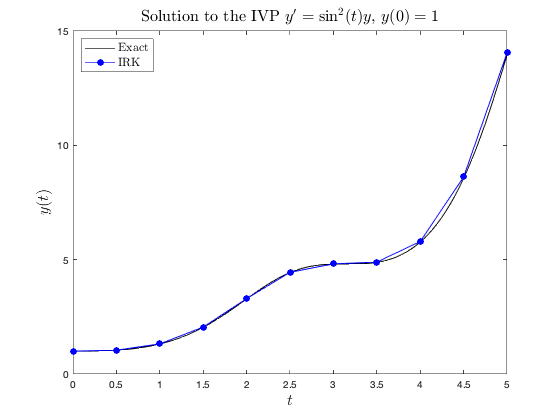

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solution to the IVP $y'=\sin^2(t)y$, $y(0)=1$", 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'IRK');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

We can see here that the solution computed using this IRK method (which is of order 3) closely matches the exact solution.

## Summary

- The stage values in an Implicit Runge-Kutta (IRK) method are defined using implicit equations.

- The $A$ matrix of an IRK method has non-zero elements on the main diagonal or upper triangular region.

- IRK methods use fewer stages to achieve the same accuracy as Explicit Runge-Kutta (ERK) methods.

- The derivation of IRK methods involves choosing values of $a_{ij$, $b_i$ and $c_i$ to satisfy some order conditions.

- IRK methods have better stability properties than ERK methods meaning they can be used to solve stiff ODEs with which ERK methods are unsuitable.

- IRK methods require an iterative method such as the Jacobi method to calculate the stage values.

- IRK methods are more computationally expensive when applied to non-stiff methods than ERK methods.

## Exercises

1.    Show that the Radau IA derived in example 3 is a third-order method.

2.    Determine the order of the following IRK method


$$\begin{array}{c|ccc}
0 & 0 & 0 \\
\frac{1}{2} & \frac{1}{4} & \frac{1}{4} & 0 \\
1 & 0 & 1 & 0 \\
& \frac{1}{6} & \frac{2}{3} & \frac{1}{6}
\end{array}$$


3.    Derive a third-order Radau IIA method.

4.    Derive a two-stage second-order SDIRK method with $c_1=\frac{1}{4}$.

5.   Using pen and a calculator and working to 4 decimal places, calculate the first step of your IRK method derived in question 4 to solve the following IVP using a step length of $h=0.4$


$$y'=ty, \qquad t\in[0, 2], \qquad y(0)=1.$$


6.    The exact solution to the IVP in question 5 is $y=e^{t^2/2}$. Using MATLAB repeat question 5 for the full domain and produce a table comparing the numerical and exact solutions and plot the numerical solutions and exact solutions on the same set of axes.

## Functions

#### IRK solver

function [t, y] = irk(f, tspan, y0, h, A, b, c)

% Calculates the solution to an initial value problem using an implicit
% Runge-Kutta method defined by A, b and c

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1))/ h);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, 1);
t(1) = tspan(1);
y(1) = y0;

% Loop through steps
for n = 1 : nsteps
    
    % Solve for Y values using the Jacobi method
    Y = ones(size(b));
    for k = 1 : 100
        Ynew = y(n) + h * A * f(t(n) + c * h, Y);
        
        % Check for convergence
        if max(abs(Ynew - Y)) < 1e-6
            break
        end
        
        % Update Y
        Y = Ynew;
    end
    
    % Calculate the solution at the next step
    y(n+1) = y(n) + h * b' * f(t(n) + c * h, Y);
    t(n+1) = t(n) + h;
    
end

end